# Create a Presentation Programmatically

This example shows how to create a PowerPoint® presentation by using the MATLAB® API for PowerPoint (PPT API). The example generates these slides: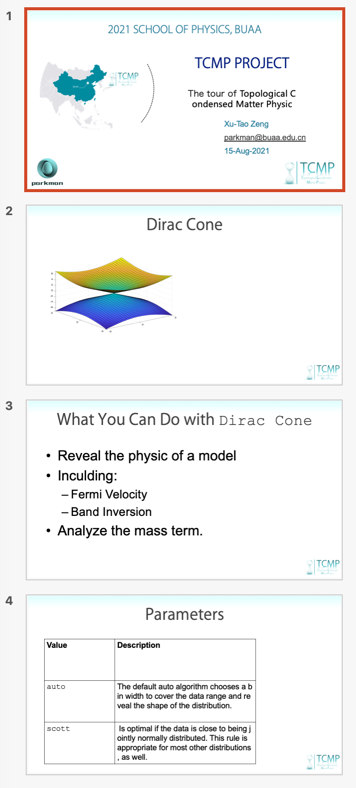

To programmatically create a presentation:

- Import the PPT API package.

- Create a presentation container.

- Add slides.

- Add content to the slides.

- Generate the presentation.

## Import the PPT API Package

The PPT API classes belong to the `mlreportgen.ppt` package. Import this package so that you do not have to include the package name when you call the PPT API object constructors and methods.

import mlreportgen.ppt.*

## Create a Presentation Container

Create an `mlreportgen.ppt.Presentation` object to contain the presentation. For this example, specify that the output file name is `myPresentation` and do not specify a template.

ppt = Presentation('myPresentation.pptx','TCMP_templete.pptx');

Because you did not specify a template, the PPT API uses the default template. A template defines the default slide layouts and styles. To create a custom template, see [Set Up a PowerPoint Template](docid:ml_rptgen_ug#buxwl22-13). You can override the default style defined by a template by using format properties and objects. See [Presentation Formatting Approaches](docid:ml_rptgen_ug#buxwl22-16).

## Add Slides and Slide Content

To add a slide, use the `add` method and specify a slide layout that is available in the template. See [Set Up a PowerPoint Template](docid:ml_rptgen_ug#buxwl22-13). This example uses these slide layouts that are included with the default template:

- `Title Slide` 

- `Title and Picture`

- `Title and Content`

- `Title and Table`

To add content to a slide, use the `replace` method to replace content placeholders with the new content. For more information about adding and replacing content, see [Add and Replace Presentation Content](docid:ml_rptgen_ug#bux0839-1). To use the `replace` method, you must specify the name that identifies a placeholder in the slide layout. For example, the `Title Slide` layout has a `Title` placeholder and a `Subtitle` placeholder. For information about how to find the content placeholder names for a particular slide layout, see [Access PowerPoint Template Elements](docid:ml_rptgen_ug#buxwl22-17).

### Add a Title Slide

To add a title slide, use the `Title Slide` layout.

titleSlide = add(ppt,'Title Slide');

The `Title Slide` layout has these placeholders:

- `Title`

- `Subtitle`

Replace the `Title` placeholder with the title text.

replace(titleSlide,'Title','TCMP PROJECT');

Build the title text in pieces so that you can format the `histogram` function name in a different font.

subtitleText = Paragraph('The tour of ');
ProjectName = Text('Topological Condensed Matter Physic');
ProjectName.Font = 'Microsoft YaHei UI';
append(subtitleText,ProjectName);

Replace the `Subtitle` placeholder with the text contained in `SubtitleText`.

replace(titleSlide,'Subtitle',subtitleText);

Author Email and Date

Author = 'Xu-Tao Zeng';
replace(titleSlide,'Author',Paragraph(Author));
Email = 'parkman@buaa.edu.cn';
Emaillink = ExternalLink(Email,Email);
replace(titleSlide,'Email',Paragraph(Emaillink));
replace(titleSlide,'Date',Paragraph(date));
%append(subtitleText,["";"Xu-Tao Zeng"]);

### Add a Slide with a Picture

Create an image file to use for the slide picture.

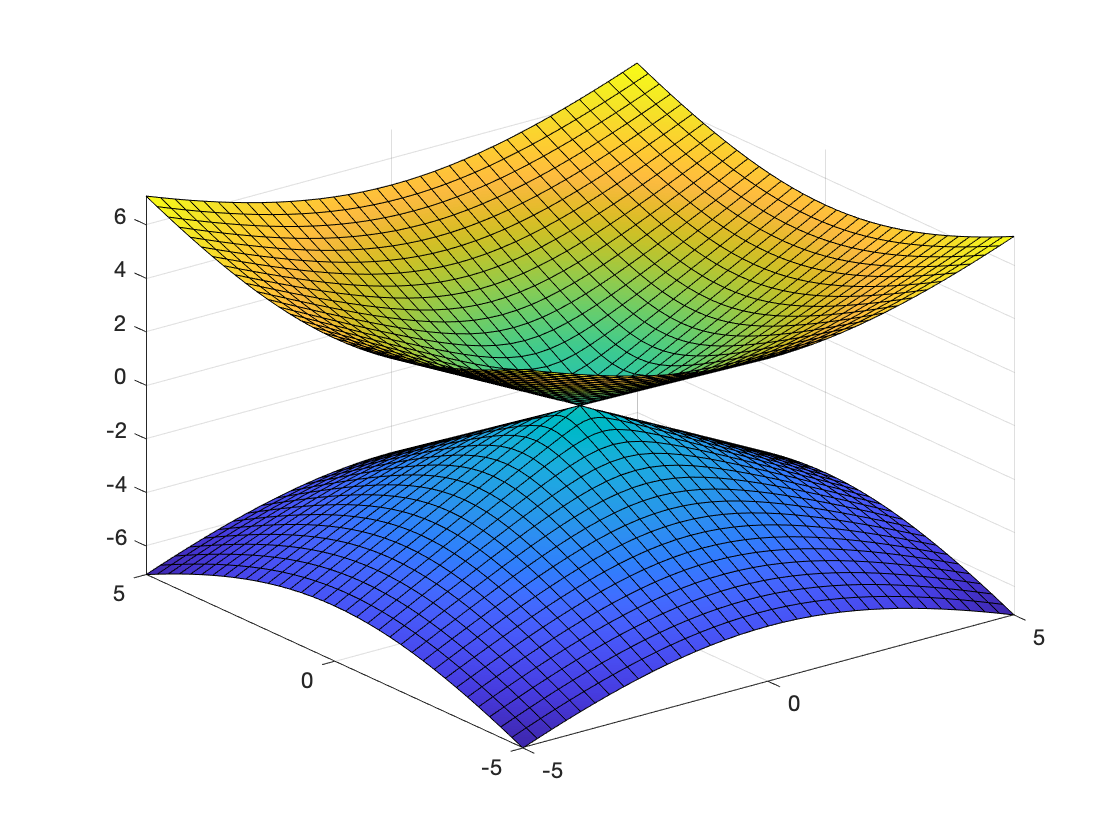

syms kx ky real;
E = sqrt(kx^2+ky^2);
h = fsurf([-E;E]);
saveas(gcf,'DiracCone.png');

Create an `mlreportgen.ppt.Picture` object from the image file.

plot1 = Picture('DiracCone.png');

Add a picture slide to the presentation by using a `Title and Picture` layout. 

pictureSlide = add(ppt,'Title and Picture 1');

The `Title and Picture` layout has these placeholders:

- `Title`

- `Picture`

Replace the `Title` placeholder with the title text and the `Picture` placeholder with `plot1`.

replace(pictureSlide,'Title','Dirac Cone');
replace(pictureSlide,'Fig1',plot1);


The contents of an image file are copied into the presentation when the presentation is closed. Do not delete or overwrite the image file before the presentation is closed. If your presentation program creates multiple image files, give them unique file names.

### Add a Slide with Text

To add a slide with text, use the `Title and Content` layout.

textSlide = add(ppt,'Title and Content 1');

The `Title and Content` layout has these placeholders:

- `Title`

- `Content`

Build the title text in pieces so that you can format the `histogram` function name in a different font.

titleText = Paragraph('What You Can Do with ');
func = Text('Dirac Cone');
func.Font = 'Courier New';
append(titleText,func);


Replace the `Title` and `Content` placeholders.

replace(textSlide,'Title',titleText);
replace(textSlide,'Content',{'Reveal the physic of a model',...
'Inculding:',{'Fermi Velocity','Band Inversion'},...
'Analyze the mass term.'});


### Add a Slide with a Table

To add a slide with a table, use the `Title and Table` layout. 

tableSlide = add(ppt,'Title and Table 1');

`The Title and Table` layout has these placeholders:

- `Title`

- `Table`

Replace the `Title` placeholder.

replace(tableSlide,'Title','Parameters');

You can use several approaches to create a table. See [Create and Format Tables](docid:ml_rptgen_ug#buxwl22-29). This example builds a table row by row.

- Create a table as an  `mlreportgen.ppt.Table` object.

- Create an `mlreportgen.ppt.TableRow` object for each row of the table.

- Create `mlreportgen.ppt.TableEntry` objects and append them to the table rows.

paramTable = Table();
colSpecs(2) = ColSpec('6in');
colSpecs(1) = ColSpec('3in');
paramTable.ColSpecs = colSpecs;

tr1 = TableRow();
tr1.Style = {Bold(true)};

tr1te1Text = Paragraph('Value');
tr1te2Text = Paragraph('Description');
tr1te1 = TableEntry();
tr1te2 = TableEntry();
append(tr1te1,tr1te1Text);
append(tr1te2,tr1te2Text);
append(tr1,tr1te1);
append(tr1,tr1te2);

tr2 = TableRow();
tr2te1Text = Paragraph('auto');
tr2te1Text.Font = 'Courier New';
tr2te2Text = Paragraph('The default auto algorithm chooses a bin width to ');
append(tr2te2Text,'cover the data range and reveal the shape of the distribution.');
tr2te1 = TableEntry();
tr2te2 = TableEntry();
append(tr2te1,tr2te1Text);
append(tr2te2,tr2te2Text);
append(tr2,tr2te1);
append(tr2,tr2te2);

tr3 = TableRow();
tr3te1Text = Paragraph('scott');
tr3te1Text.Font = 'Courier New';
tr3te2Text = Paragraph(' Is optimal if the data is close ');
append(tr3te2Text,'to being jointly normally distributed. This rule is ');
append(tr3te2Text,'appropriate for most other distributions, as well.');
tr3te1 = TableEntry();
tr3te2 = TableEntry();
append(tr3te1,tr3te1Text);
append(tr3te2,tr3te2Text);
append(tr3,tr3te1);
append(tr3,tr3te2);

append(paramTable,tr1);
append(paramTable,tr2);
append(paramTable,tr3);

Replace the `Table` placeholder with `paramTable`.


replace(tableSlide,'Table',paramTable);

## Generate and View the Presentation

close(ppt);
rptview(ppt);

*Copyright 2019 The MathWorks, Inc.*